## encoder

### part 1

global SAMPLEPERSEC ALPHA;
SAMPLEPERSEC = 100;
ALPHA = 1;
characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];

Mapset = cell(32,2);

for i = 1:length(characters)
    Mapset{i,1} = characters(i);
    Mapset{i,2} = dec2bin(i-1,5); 
end
Mapset

Mapset = 32×2 cell array
    {'a'}    {'00000'}
    {'b'}    {'00001'}
    {'c'}    {'00010'}
    {'d'}    {'00011'}
    {'e'}    {'00100'}
    {'f'}    {'00101'}
    {'g'}    {'00110'}
    {'h'}    {'00111'}
    {'i'}    {'01000'}
    {'j'}    {'01001'}
    {'k'}    {'01010'}
    {'l'}    {'01011'}
    {'m'}    {'01100'}
    {'n'}    {'01101'}
    {'o'}    {'01110'}
    {'p'}    {'01111'}
    {'q'}    {'10000'}
    {'r'}    {'10001'}
    {'s'}    {'10010'}
    {'t'}    {'10011'}
    {'u'}    {'10100'}
    {'v'}    {'10101'}
    {'w'}    {'10110'}
    {'x'}    {'10111'}
    {'y'}    {'11000'}
    {'z'}    {'11001'}
    {' '}    {'11010'}
    {'.'}    {'11011'}
    {','}    {'11100'}
    {'!'}    {'11101'}


- `SAMPLEPERSEC` تعداد نمونه‌ها در هر ثانیه را تنظیم می‌کند.

- `characters` شامل کاراکترهای قابل کدگذاری است.

- `Mapset` شامل کاراکترها و معادل دودویی ۵ بیتی آن‌ها است.

### part 2

در این بخش، روند کدگذاری پیام به صورت زیر انجام می‌شود:

- ابتدا یک جدول `Mapset` ایجاد می‌شود که هر کاراکتر از پیام ورودی (مثلاً حروف الفبا، فواصل و علائم نگارشی) به کد دودویی معادل خود نگاشت می‌شود. این کار برای تبدیل پیام به یک رشته دودویی انجام می‌شود.

- سپس، پیام ورودی به رشته‌ای از کدهای دودویی تبدیل می‌شود. این فرآیند با استفاده از `Mapset` انجام می‌شود تا هر کاراکتر از پیام به معادل دودویی خود تبدیل شود.

- پس از کدگذاری، پیام به بخش‌های کوچکتر تقسیم می‌شود. این تقسیم‌بندی بر اساس یک پارامتر به نام `transmission_speed` انجام می‌شود که طول هر بخش را مشخص می‌کند. این بخش‌ها برای پردازش و ارسال راحت‌تر آماده می‌شوند.

- سپس، هر بخش دودویی به یک سیگنال سینوسی تبدیل می‌شود. برای هر بخش دودویی، یک سیگنال سینوسی خاص تولید می‌شود که نماینده آن بخش از پیام است.

- در نهایت، تمامی سیگنال‌ها که هرکدام نمایانگر یک بخش از پیام هستند، به یک سیگنال پیوسته ترکیب می‌شوند. این سیگنال پیوسته در نهایت به عنوان خروجی برای ارسال پیام به سیستم گیرنده استفاده می‌شود.

در کل، روند کدگذاری پیام به این صورت است که ابتدا پیام به کد دودویی تبدیل می‌شود، سپس به بخش‌های کوچکتر تقسیم و در نهایت به سیگنال‌های سینوسی برای ارسال تبدیل می‌شود.

function encodedText = encodeTextWithMapset(Mapset, text)

tmp_encode = '10011001001001010011'

    % split code and char
    characters = [Mapset{:, 1}];
    codes = Mapset(:, 2);

    % map to char index
    [~, idx] = ismember(text, characters);
    
    % encode
    encodedText = strjoin(codes(idx), '');
end

tmp_encode = encodeTextWithMapset(Mapset, 'test')

- کاراکترهای ورودی را به رشته دودویی معادل آن‌ها بر اساس `Mapset` تبدیل می‌کند.

- از تابع `ismember` برای یافتن اندیس کاراکترها استفاده می‌شود.

- نتیجه نهایی رشته دودویی ترکیب‌شده است.

function semgments = segment_massage(transmission_speed, binary_message)

tmp_segments = 1×7 cell array
    {'100'}    {'110'}    {'010'}    {'010'}    {'010'}    {'100'}    {'11'}


    semgments = {};
    for i = 1:transmission_speed:strlength(binary_message)
        if i + transmission_speed - 1 <= strlength(binary_message)
            segment = binary_message(i:i+transmission_speed-1);
        else
            segment = binary_message(i:end);
        end
       semgments{end+1} = segment;
    end
end

tmp_segments = segment_massage(3, tmp_encode)

- پیام دودویی را به بخش‌هایی با طول `transmission_speed` تقسیم می‌کند.

- اگر طول پیام کامل نباشد، بخش آخر کوتاه‌تر خواهد بود.

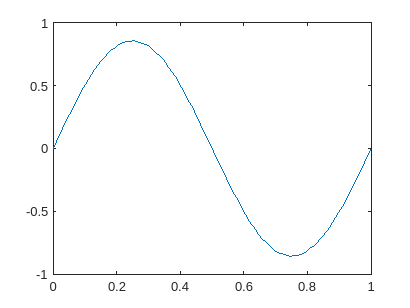

function signal = binaryToSignal(segment, t, transmission_speed)
    global ALPHA;

    max_value = 2^transmission_speed - 1;
    signal = zeros(size(t));

    for i = 0:max_value
        if strcmp(dec2bin(i, transmission_speed), segment)
            signal = (i / max_value) * ALPHA * sin(2 * pi * t);
        end
    end
end

tmp_x = linspace(0, 1, SAMPLEPERSEC);
plot(tmp_x, binaryToSignal(tmp_segments(2), tmp_x, 3));

- بخش دودویی ورودی را به سیگنال سینوسی تبدیل می‌کند.

- مقدار سیگنال بر اساس مقدار دودویی نسبت به حداکثر مقدار ممکن تنظیم می‌شود.

- از تابع `strcmp` برای مقایسه رشته‌ها استفاده می‌کند.

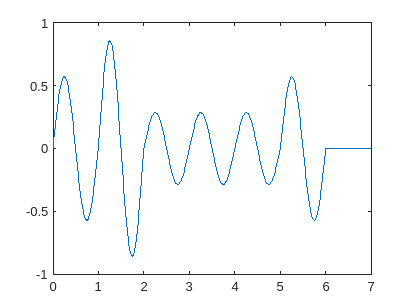

function encoded_message = convert_to_signal(semgments, transmission_speed)
    global SAMPLEPERSEC;
    t = linspace(0, 1, SAMPLEPERSEC);


    encoded_message = zeros(1, length(t) * length(semgments));

    for i = 1:length(semgments)
       segment = semgments{i};
       signal = binaryToSignal(segment, t, transmission_speed);
        start_idx = (i-1)*length(t) + 1;
        end_idx = i*length(t);
        encoded_message(start_idx:end_idx) = signal;
    end
end

tmp_signal = convert_to_signal(tmp_segments, 3);
tmp_x = linspace(0, length(tmp_signal)/SAMPLEPERSEC, length(tmp_signal)); 
plot(tmp_x ,tmp_signal);

- تمام بخش‌های دودویی را به سیگنال‌های سینوسی تبدیل و در یک سیگنال پیوسته قرار می‌دهد.

- از `SAMPLEPERSEC` برای تنظیم تعداد نمونه‌ها استفاده می‌کند.

- سیگنال نهایی از ترکیب تمامی بخش‌ها ساخته می‌شود.

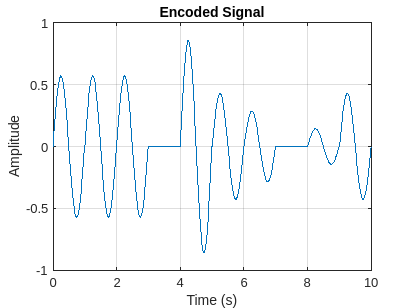

function encoded_message = coding_amp(message, transmission_speed, Mapset)
    message = char(message);
    binary_message = encodeTextWithMapset(Mapset,message);

    semgments = segment_massage(transmission_speed, binary_message);


    encoded_message = convert_to_signal(semgments, transmission_speed);

end

- پیام ورودی را به کد دودویی تبدیل می‌کند.

- پیام دودویی را به بخش‌های کوچک‌تر تقسیم می‌کند.

- سیگنال پیوسته را با استفاده از بخش‌های دودویی تولید می‌کند.

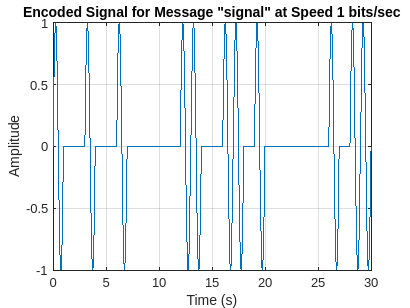

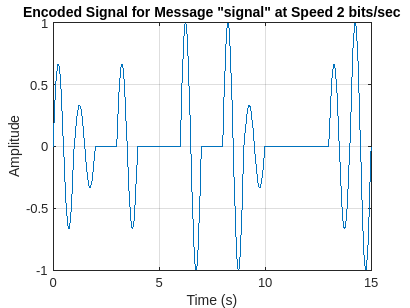

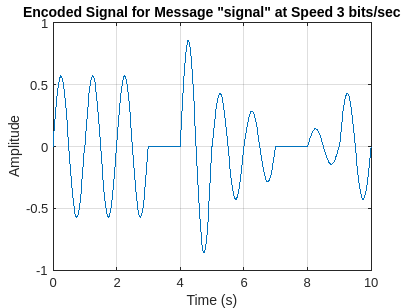

message = 'signal';
speed = 3;
encoded_message = coding_amp(message, speed, Mapset);

t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal');
grid on;

- سیگنال کدگذاری‌شده رسم می‌شود.

- برچسب‌های زمان و دامنه تنظیم شده‌اند.

- `grid on` برای نمایش بهتر نمودار فعال می‌شود.

### part 3

این کد پیام "signal" را با سرعت‌های ارسال اطلاعات ۱، ۲ و ۳ بیت بر ثانیه رمزگذاری کرده و سیگنال‌های رمزگذاری‌شده را در نمودارهای جداگانه بر اساس زمان رسم می‌کند.

speeds = [1, 2, 3];
encoded_signals = cell(1, length(speeds));

for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_amp(message, speed, Mapset);
    
    encoded_signals{i} = encoded_message;  % Store the encoded message in the array
    
    figure;
    t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
    plot(t, encoded_message);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Encoded Signal for Message "signal" at Speed %d bits/sec', speed));
    grid on;
end

### part 4

function bits_Mapset = createBitsMapset(bit_rate)
    bits_Mapset = cell(2^bit_rate, 1);
    for i = 1:2^bit_rate
        bits_Mapset{i} = dec2bin(i - 1, bit_rate);
    end
end

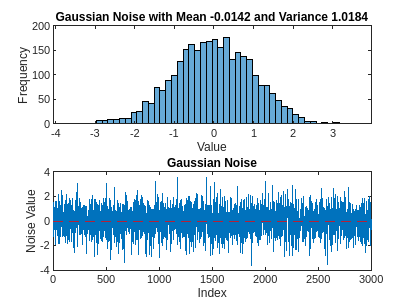

function thresholds = get_thresholds(bit_rate)
    threshold = 1 / (2 * (2^bit_rate - 1));
    thresholds = zeros(1, 2^bit_rate - 1);

    for i = 1:(2^bit_rate)
        thresholds(i) = (i * 2 - 1) * threshold;
    end
end

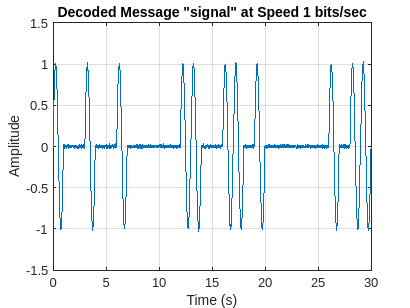

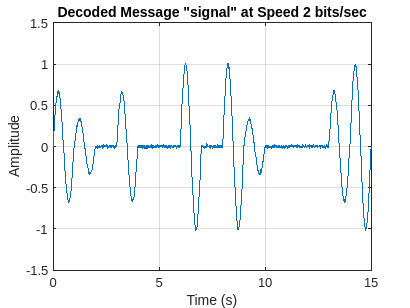

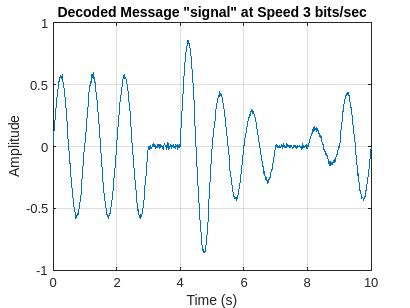

function bits = extractBitsFromResult(signal, bits_Mapset, thresholds, segment_length)
    bits = [];
    t = 0:0.01:1;
    global ALPHA;
    compare_signal = ALPHA * 2 * sin(2 * pi * t);
   
    for i = 1:(length(signal)/segment_length)
        
        segment_start = round((i-1) * segment_length) + 1;
        segment_end = round(i * segment_length);
        segment_signal = signal(segment_start:segment_end);

        result_segment = 0.01 * xcorr(compare_signal, segment_signal);

        for j = 1:length(thresholds)
            if max(result_segment) < (ALPHA * thresholds(j))  
                bits = [bits, bits_Mapset{j}];
                break;
            end

        end
    end
end


function output_string = decodeBits(bits, Mapset)
    
    bit_rate = 5;
    n_chars = length(bits) / bit_rate;

    output_string = '';

    for i = 1:n_chars
        bit_chunk = bits((i-1)*bit_rate + 1:i*bit_rate);
        for j = 1:length(Mapset)
            if strcmp(bit_chunk, Mapset{j, 2})
                output_string = [output_string, Mapset{j, 1}];
                break;
            end
        end
    end
end


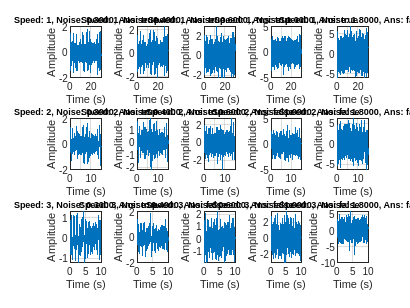

function output_string = decoding_map(signal, bit_rate, Mapset)    
    bits_Mapset = createBitsMapset(bit_rate);

    thresholds = get_thresholds(bit_rate);

    bits = extractBitsFromResult(signal, bits_Mapset, thresholds, 100);

    % disp(bits);

    output_string = decodeBits(bits, Mapset);

    
    % disp(['Decoded string: ', output_string]);

end

decoding_map(encoded_message,speed, Mapset);
decoding_map(cell2mat(encoded_signals(1)), 1, Mapset);
decoding_map(cell2mat(encoded_signals(2)), 2, Mapset);
decoding_map(cell2mat(encoded_signals(3)), 3, Mapset);

### part 5

**ولید نویز گوسی با میانگین صفر و واریانس یک**:

- با استفاده از دستور `randn(1, 3000)`, نویز گوسی با میانگین صفر و واریانس یک تولید می‌شود.

- بررسی می کنیم نویز خواص گفته شده را داشته باشد.

noise = randn(1, 3000);
noise_mean = mean(noise);
noise_variance = var(noise);

figure;
subplot(2, 1, 1);
histogram(noise, 50);
title(sprintf('Gaussian Noise with Mean %.4f and Variance %.4f', noise_mean, noise_variance));
xlabel('Value');
ylabel('Frequency');

subplot(2, 1, 2);
plot(noise);
title('Gaussian Noise');
xlabel('Index');
ylabel('Noise Value');
hold on;
yline(noise_mean, 'r--'); 

### part 6

**افزایش واریانس نویز**:

- با ضرب دستور `randn` در یک عدد دلخواه σ\sigmaσ، می‌توان واریانس نویز را تغییر داد.

sigma = sqrt(0.0001);
message = 'signal';
speeds = [1, 2, 3];

for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_amp(message, speed, Mapset);
    
    noise = sigma * randn(1, length(encoded_message));
    noisy_message = encoded_message + noise;
    
    result = decoding_map(noisy_message,speed, Mapset);
    figure;
    t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
    plot(t, noisy_message);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Decoded Message "%s" at Speed %d bits/sec',result, speed));
    grid on;
end

همانطور که دیدیم با این مقدار نویز مشکلی برای خواندن پیام به وجود نمی آید و با هر سه حالت می توان پیام را خواند.

### part 7

برای شبیه‌سازی و بررسی مقاومت پیام در برابر نویز با قدرت‌های مختلف، می‌توانیم مراحل زیر را انجام دهیم:

- **افزایش تدریجی قدرت نویز**:

- قدرت نویز را در چندین مرحله افزایش می‌دهیم (مثلاً از مقدار اولیه 0.0001 تا مقادیر بزرگتر مانند 0.01، 0.1 و ...).

- برای هر مقدار نویز، پیام کدگذاری‌شده را نویزدار کرده و سپس آن را رمزگشایی می‌کنیم.

- **بررسی نرخ بیت‌های مختلف**:

- این روند را برای سه نرخ مختلف (1، 2 و 3 بیت در ثانیه) تکرار کرده و نتایج رمزگشایی را ثبت می‌کنیم.

- **گزارش نتایج**:

- برای هر مقدار نویز، بررسی می‌کنیم که آیا پیام به درستی رمزگشایی شده است یا خیر.

- مقایسه می‌کنیم که کدام یک از سه نرخ بیت به نویز مقاوم‌تر بوده و آیا نتایج با پیش‌بینی‌ها مطابقت دارد یا نه.

message = 'signal';
speeds = [1, 2, 3];
% noise_variances = [0.001, 0.01, 0.1, 0.5, 1];
noise_variances = [0.3 ,0.4, 0.6, 1, 1.8];


figure;

for i = 1:length(speeds)
    speed = speeds(i);
    encoded_message = coding_amp(message, speed, Mapset);
    
    for j = 1:length(noise_variances)
        noise_power = noise_variances(j);
        noise = noise_power * randn(size(encoded_message));
        
        subplot(length(speeds), length(noise_variances), (i-1)*length(noise_variances) + j);
        noisy_signal = encoded_message + noise;

        result = decoding_map(noisy_signal,speed, Mapset);
        t = linspace(0, length(noisy_signal)/SAMPLEPERSEC, length(noisy_signal)); 
        plot(t, noisy_signal);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(sprintf('Speed: %d, Noise: %.4f, Ans: %s', speed, noise_power, string(strcmp(result, message))), "FontSize",  7);
        grid on;
    end
end

**تحلیل:**

- **افزایش بیت‌ریت و کاهش مقاومت**:

- با افزایش بیت‌ریت (۱ به ۳ بیت بر ثانیه)، مقدار اطلاعاتی که در هر واحد زمان ارسال می‌شود بیشتر می‌شود.

- در بیت‌ریت بالا، فاصله میان سطوح مختلف سیگنال کاهش می‌یابد. این فاصله کمتر، باعث می‌شود که حتی مقدار کمی از نویز بتواند سیگنال را به اشتباه تفسیر کند.

- به عبارت دیگر، با افزایش بیت‌ریت، احتمال **خطای تشخیص** در گیرنده بیشتر می‌شود، زیرا سیگنال‌ها به دلیل نویز دچار هم‌پوشانی می‌شوند.

- **بیت‌ریت پایین‌تر و مقاومت بالاتر**:

- در بیت‌ریت پایین‌تر (۱ بیت بر ثانیه)، فاصله میان مقادیر مختلف سیگنال بیشتر است.

- این فاصله بیشتر باعث می‌شود که حتی در حضور نویز، سیگنال با دقت بالاتری تفسیر شود.

- در واقع، فاصله بزرگتر بین سطوح سیگنال، مقاومت آن را نسبت به تغییرات ناشی از نویز افزایش می‌دهد.

با افزایش قدرت نویز، سیگنال با بیت‌ریت بالاتر سریع‌تر تحت تأثیر قرار می‌گیرد و احتمال خطا در تشخیص افزایش می‌یابد. این امر به دلیل کاهش فاصله میان سطوح سیگنال در بیت‌ریت‌های بالا است که باعث کاهش **نسبت سیگنال به نویز** و افزایش حساسیت به نویز می‌شود.

### part 8

بیشترین واریانس نویز که بیت‌ریت ۳ مقاوم بود، **۰.۴**، بیت‌ریت ۲، **۰.۶**، و بیت‌ریت ۱، **۱.۸** بود. بیت‌ریت کمتر باعث مقاومت بیشتر در برابر نویز می‌شود، زیرا فاصله بین سطوح سیگنال بزرگتر است و احتمال تداخل نویز کمتر می‌شود.